# Monte Carlo of GoHorse Optimization - *fminsearch(.)*

Default config

close all;
clear;
clc;
set(0,'defaultfigurecolor',[1 1 1]);

Initialize variables and set the Monte Carlo configurations

MCruns = 100;

par = cell(MCruns,1);
J = cell(MCruns,1);
e_flag = cell(MCruns,1);
cruze = cell(MCruns,1);

## Generate the data or load pre-saved ones

Define the number of information data

WL = autoGen(14);
[dtd,dtn,A] = alertness_gen(2,WL,'random','not');
%load('monte_data.mat');

est_d = 7;

dte.y = dtd.y(1:est_d); dte.t = dtd.t(1:est_d);
dte.init = dtd.initial(1:est_d); dte.final = dtd.final(1:est_d); 
dte.valid.y = dtd.y(est_d+1:end); dte.valid.t = dtd.t(est_d+1:end);
dte.valid.init = dtd.initial(est_d+1:end); dte.valid.final = dtd.final(est_d+1:end);

A.valid.Ad = A.Ad(est_d+1:end); A.valid.td = A.td(est_d+1:end);
A.valid.An = A.An(est_d+1:end); A.valid.tn = A.tn(est_d+1:end);

Create  a variable for noise manipulation on simulation

y_c = dte.y;

## Optimization setup

options = optimset('Display','off','MaxIter',100,'UseParallel',true);
prop = .2;

## Real parameters

rPar(1) = pi/12; %omega
rPar(2) = 1/0.0353; %tau
rPar(3) = 2.52; %M
rPar(4) = -16.835*pi/12; %cPhase
rPar(5) = 2.4; %offset
rPar(6) = 14.3; %y_oo
rPar(7) = 2.6247; %tau_e

TexNames{1} = '$$\omega_n$$'; 
TexNames{2} = '$$\tau$$';
TexNames{3} = '$$M$$'; 
TexNames{4} = '$$\phi_{c}$$'; 
TexNames{5} = '$$A_{DC}$$'; 
TexNames{6} = '$$y_{\infty}$$';
TexNames{7} = '$$\tau_{e}$$';

## Initialize the Monte Carlo Simulations

for mc = 1 : MCruns
    
    rng('shuffle');
    
    noise_nat = 'white';
    SNR = 40;
    to = cell2mat(dte.t);

    if strcmp(noise_nat,'white')
        e = idinput(length(cell2mat(y_c)),'rgs')*...
                                          std(cell2mat(y_c))*10^(-SNR/20);
        yo = cell2mat(y_c) + e;
    elseif strcmp(noise_nat,'colored')
        e = filter(1,[1 -.9],randn(length(cell2mat(y_c)),1));
        v = e*std(cell2mat(y_c))*10^(-SNR/20)/std(e);
        e = v;
        yo = cell2mat(y_c) + e;
    elseif strcmp(noise_nat,'noNoise')
        yo = cell2mat(y_c);
    end

    for w = 1 : length(y_c)
       ind = find((to>=dte.t{w}(1)).*(to<=dte.t{w}(end)));
       dte.y{w} = yo(ind);
    end
    
    cruze{mc} = prop.*rPar.*(rand(1,length(rPar))-.5);
    
    init = rPar + cruze{mc};
    
    [par{mc},J{mc},e_flag{mc}] = fminsearch(@ghCost,init,options,dte);
    
    disp(['Monte Carlo run ',num2str(mc),...
                             ' Quadratic Error: ',num2str(J{mc})]);
end

Monte Carlo run 1 Quadratic Error: 0.00051438
Monte Carlo run 2 Quadratic Error: 0.00061925
Monte Carlo run 3 Quadratic Error: 0.0019375


Monte Carlo run 4 Quadratic Error: 1.5953


Monte Carlo run 5 Quadratic Error: 0.0012658
Monte Carlo run 6 Quadratic Error: 0.0024818


Monte Carlo run 7 Quadratic Error: 0.00027414
Monte Carlo run 8 Quadratic Error: 0.00025891
Monte Carlo run 9 Quadratic Error: 0.0073818
Monte Carlo run 10 Quadratic Error: 0.00020555
Monte Carlo run 11 Quadratic Error: 0.0011035
Monte Carlo run 12 Quadratic Error: 0.0029244
Monte Carlo run 13 Quadratic Error: 0.0012544
Monte Carlo run 14 Quadratic Error: 0.0038382


Monte Carlo run 15 Quadratic Error: 0.00050141
Monte Carlo run 16 Quadratic Error: 0.0018886
Monte Carlo run 17 Quadratic Error: 0.016085
Monte Carlo run 18 Quadratic Error: 0.00073789
Monte Carlo run 19 Quadratic Error: 1.5383


Monte Carlo run 20 Quadratic Error: 0.0035223
Monte Carlo run 21 Quadratic Error: 0.0028207
Monte Carlo run 22 Quadratic Error: 0.014661
Monte Carlo run 23 Quadratic Error: 0.00015723
Monte Carlo run 24 Quadratic Error: 0.0022542
Monte Carlo run 25 Quadratic Error: 0.00039822
Monte Carlo run 26 Quadratic Error: 0.00059007
Monte Carlo run 27 Quadratic Error: 0.0058437
Monte Carlo run 28 Quadratic Error: 0.0009975
Monte Carlo run 29 Quadratic Error: 0.0023131
Monte Carlo run 30 Quadratic Error: 0.00029258
Monte Carlo run 31 Quadratic Error: 0.00072351
Monte Carlo run 32 Quadratic Error: 0.034804
Monte Carlo run 33 Quadratic Error: 0.00028443
Monte Carlo run 34 Quadratic Error: 0.00032234
Monte Carlo run 35 Quadratic Error: 0.0018077
Monte Carlo run 36 Quadratic Error: 0.0002749
Monte Carlo run 37 Quadratic Error: 0.00038094
Monte Carlo run 38 Quadratic Error: 0.022286
Monte Carlo run 39 Quadratic Error: 0.0004413
Monte Carlo run 40 Quadratic Error: 0.0014746
Monte Carlo run 41 Quadratic 

## Monte Carlo figures

Plot the optimization output flags propotions and the cost function results 

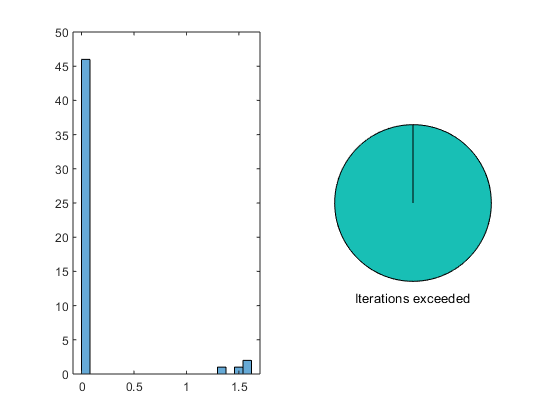

figure(2); hold on;
subplot(1,2,1);
histogram(cell2mat(J),20);
subplot(1,2,2);
labels = {'Function Terminated','Iterations exceeded','Converged to solution'};
flags = cell2mat(e_flag)'+2;
e_flags = [count(num2str(flags),"1"), count(num2str(flags),"2"), count(num2str(flags),"3")];
pie(e_flags,labels);

Generate the visualization from for the cruze signal variations

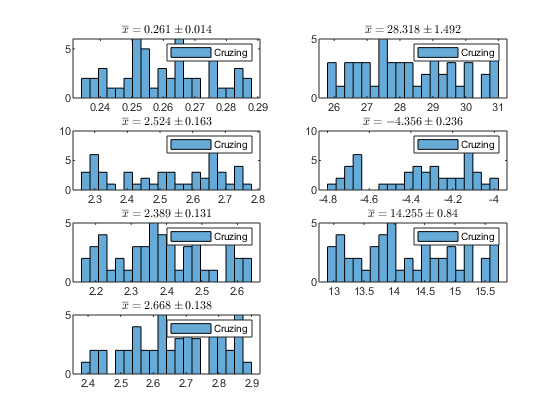

figure(3); hold on;
title('Parameters initialization cruzing','Interpreter','latex');
aux = cell2mat(cruze);
for i = 1 : 7
   subplot(4,2,i); 
   histogram(aux(:,i)+rPar(i),20); hold on;
   title(['$$\overline{x} =',num2str(round(mean(aux(:,i)+rPar(i)),3)),...
       '\pm',num2str(round(std(aux(:,i)+rPar(i)),3)),'$$'],...
       'Interpreter','latex');
   leg = TexNames{i};
   legend(leg,'Interpreter','latex');
end

Plot the proportional error for each parameter at each run

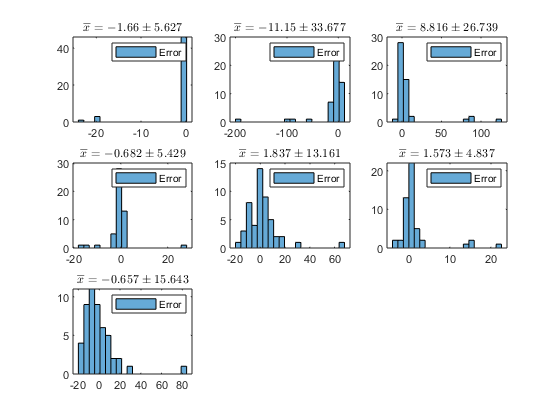

figure(4); hold on;
title('Parameters error on finalization','Interpreter','latex');
aux_i = cell2mat(par);
for i = 1 : 7
   subplot(3,3,i);
   e_prop = 100.*(rPar(i) - aux_i(:,i))/rPar(i); 
   histogram(e_prop,20);
   title(['$$\overline{x} =',num2str(round(mean(e_prop),3)),...
       '\pm',num2str(round(std(e_prop),3)),'$$'],'Interpreter','latex');
   leg = TexNames{i};
   legend(leg,'Interpreter','latex'); 
end